# Estudio de la Cinemática y Dinámica de un robot SCARA con tres grados de libertad

Nombre:

Cabrera Cruz Carlo Alejandro

Mauricio Flores Pradel

Rodriguez Torres Angel Adrian

Materia: Robotica

Grupo: 1

Profesor:M.I. Erik Peña Medina

## Resumen

Este trabajo estudia el funcionamiento de un robot SCARA con tres eslabones y tres articulaciones rotacionales, uno de los cuales está fijo al sistema de referencia. El objetivo es comprender cómo se relacionan la posición, la orientación y los movimientos de cada articulación con la tarea final que el robot debe realizar. Para ello, primero se desarrolla el modelo cinemático, que permite describir la pose, las velocidades y la aceleración del robot desde su base hasta el efector final.

Más adelante, se formula el modelo dinámico de esta configuración empleando el método de Euler-Lagrange, tanto en su forma directa como inversa, lo que facilita analizar el comportamiento del sistema desde dos enfoques complementarios. Con esta integración de los modelos cinemáticos y dinámicos se busca no solo describir los movimientos, sino también entender cómo la interacción entre las juntas y los eslabones condiciona la precisión, la eficiencia y la respuesta del robot en la ejecución de sus tareas.

## Introducción:

La robótica moderna depende fundamentalmente de la capacidad para predecir y controlar con precisión el comportamiento de los manipuladores. Para lograr esto, es indispensable desarrollar un "gemelo digital", un conjunto de modelos matemáticos que describan fielmente la física del robot. El presente reporte tiene como objetivo principal el desarrollo y la documentación de los modelos cinemático y dinámico de un robot manipulador tipo SCARA de tres grados de libertad. El análisis abarca desde la descripción de la postura y el movimiento del robot hasta las fuerzas necesarias para generarlo.

Para el modelo cinemático, se emplea la convención de Denavit-Hartenberg y el uso de matrices de transformación homogénea para la cinemática directa, así como el análisis Jacobiano para el estudio de las velocidades. Para el modelo dinámico, se utiliza la formulación de Euler-Lagrange, un método robusto basado en la energía del sistema que permite determinar los torques requeridos en cada articulación.

El documento se encuentra estructurado de la siguiente manera: las secciones 2, 3 y 4 desarrollan progresivamente el modelo cinemático de la postura, velocidades y aceleraciones. La sección 5 detalla el modelo dinámico. Finalmente, en la sección 6 se presentan las conclusiones del trabajo realizado.

Definición de funciones 

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelado del robot Scara

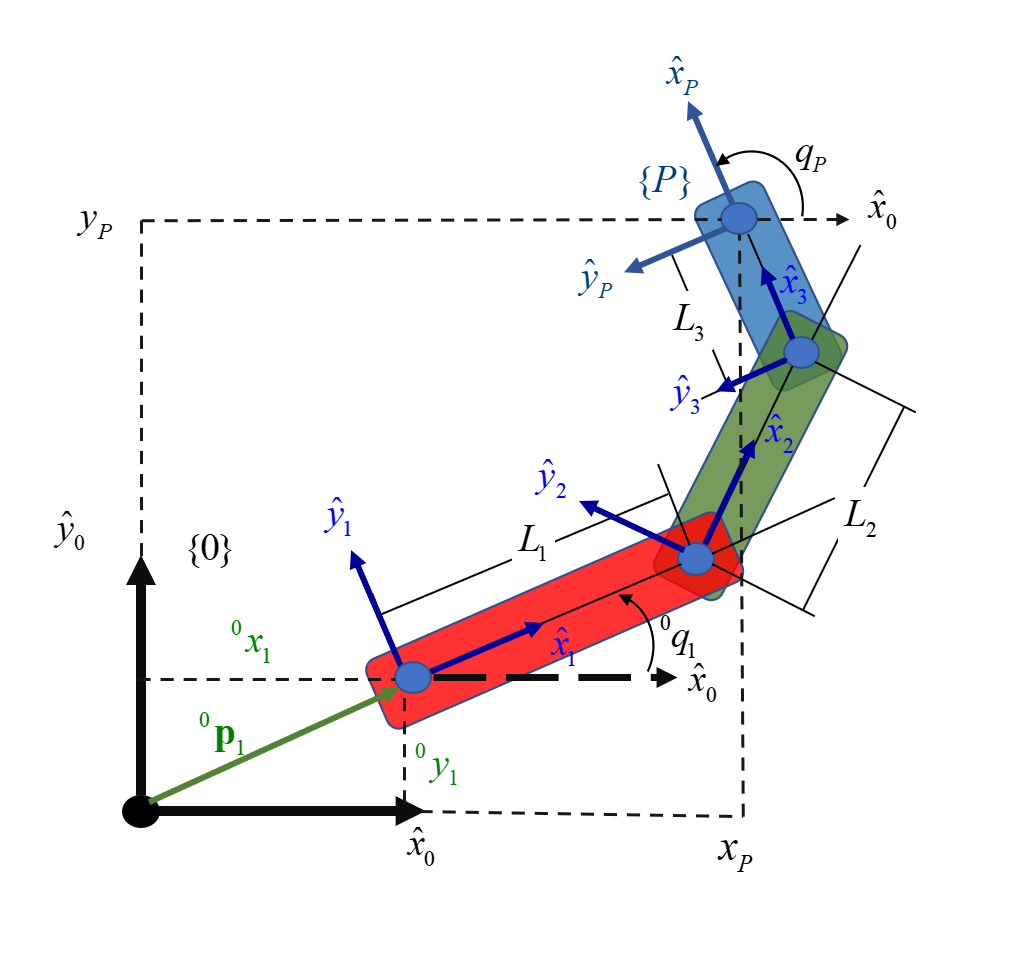

### Planteamiento del modelo cinemático de la posición

El modelo cinemático directo nos permite determinar la posición y orientación del efector final del robot a partir de los valores conocidos de sus ángulos articulares. Para lograr esto, se modela cada eslabón y articulación como un sistema de coordenadas independiente. La relación entre estos sistemas se establece mediante matrices de transformación homogénea (T), las cuales representan la traslación y rotación entre un sistema y el siguiente.

La matriz de transformación total, que describe la ubicación del efector final con respecto a la base, se obtiene multiplicando secuencialmente las matrices de cada eslabón. A continuación, se presenta el diagrama del robot analizado y el desarrollo del código para obtener este modelo.

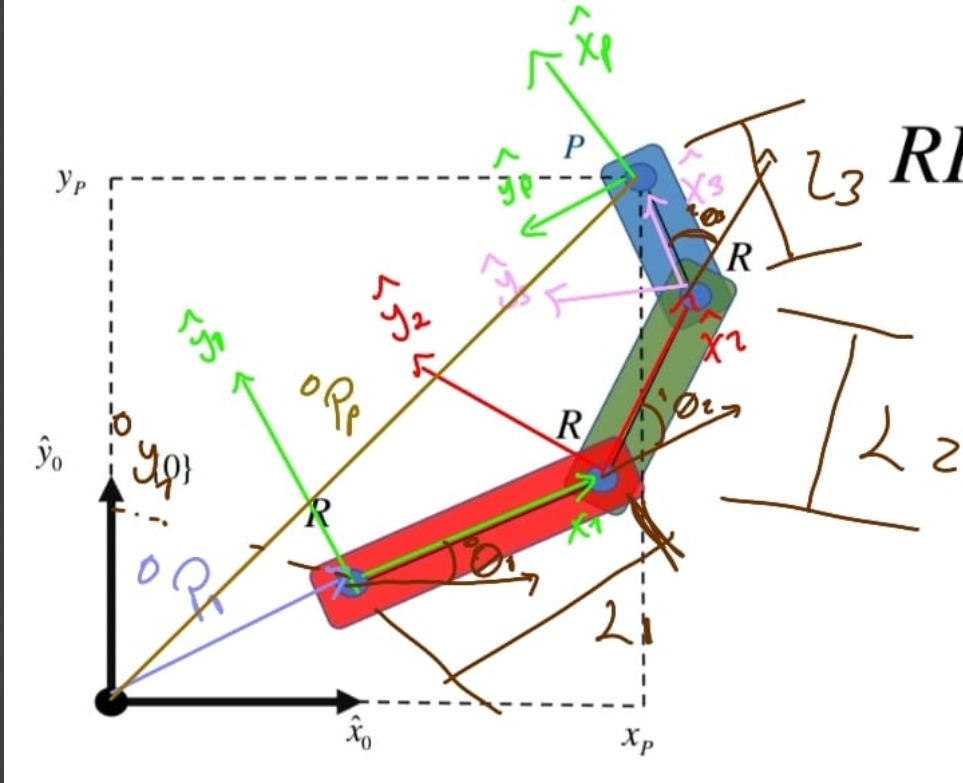

Como este movimiento ocurre dentro de un plano, por ahora no consideramos la posición sobre el eje Z. Nuestro punto de referencia es el eje X, que nos permite observar la rotación que realiza cada eslabón alrededor del eje Z. El eje X se orienta de forma paralela a la longitud del eslabón, lo que facilita describir los cambios en su orientación.

Como se mencionó anteriormente, se empleó el modelo de Denavit-Hartenberg. Esta matriz contiene la matriz de orientación, el vector de posicion y la escala del punto que se analiza.

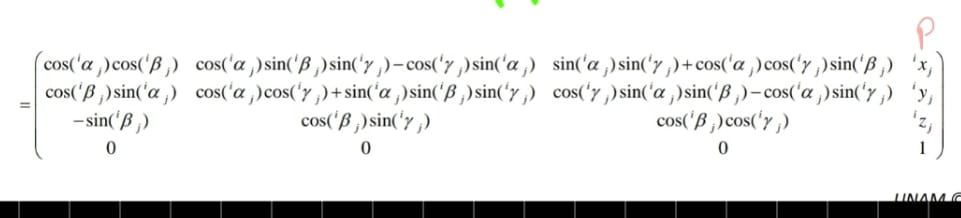

El modelo cinemático directo nos permite determinar la posición y orientación del efector final del robot a partir de los valores conocidos de sus ángulos articulares. Para lograr esto, se modela cada eslabón y articulación como un sistema de coordenadas independiente.

Un principio fundamental en este análisis, especialmente para robots con juntas rotacionales como el SCARA, es la selección de un sistema de referencia que simplifique el problema. Al analizar el movimiento desde un plano perpendicular al eje de rotación, dicho eje se observa como un simple punto. Este lugar geométrico, conocido como el plano de rotación, permite reducir un problema tridimensional a uno bidimensional, facilitando enormemente el cálculo de la posición de cualquier punto del robot.

La relación entre los sistemas de coordenadas se establece mediante matrices de transformación homogénea (T), las cuales representan la traslación y rotación entre un sistema y el siguiente.

syms x_O_1 y_O_1 theta_O_1 L_2 theta_1_2 L_3 theta_2_3 L_1

T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2 = Tij(L_1,0,0,0,0,theta_1_2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3 = Tij(L_2,0,0,0,0,theta_2_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

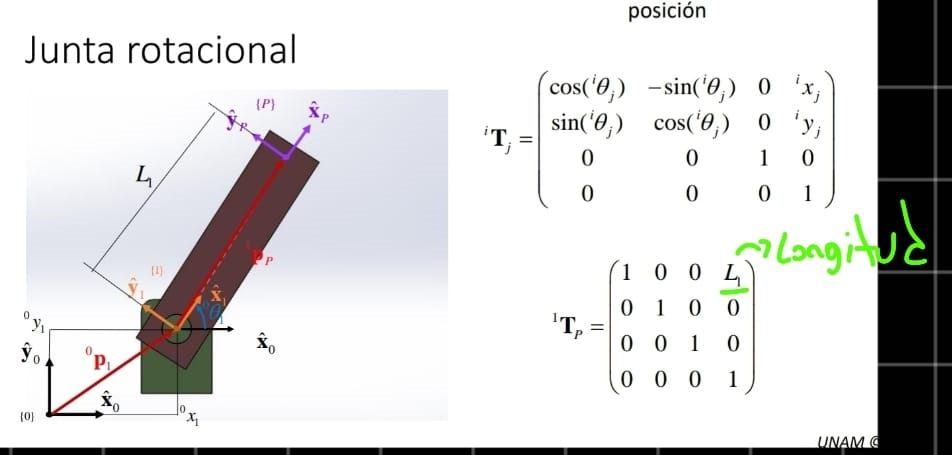

T_3_P = Tij(L_3,0,0,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$T\_O\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

Vector de postura del robot

Se extrae la información más relevante: la posición del punto **P** y el ángulo que define su orientación. Se observa que ambos valores dependen de los datos obtenidos previamente, mostrando cómo las uniones influyen en nuestro punto de interés. Estos parámetros conforman el **vector de pose**.

En esencia, este proceso permite determinar la posición y orientación del **efector final** en función de un conjunto específico de **variables articulares**

xi_O_P = [T_O_P(1,4);T_O_P(2,4);theta_O_1+theta_1_2+theta_2_3]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{1,2}+\theta_{2,3}+\theta_{O,1} \end{array}\right)$$

## Modelo Cinemático Inverso

A diferencia del modelo directo, el modelo cinemático inverso resuelve el problema opuesto: si conocemos la posición (y orientación) deseada del efector final (x, y, φ), ¿qué valores deben tomar los ángulos de las articulaciones (θ₁, θ₂, θ₃) para alcanzar dicha posición?

inv(J_theta)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$

Este problema es fundamental en la robótica para la planificación de trayectorias. Para un robot SCARA como el analizado, la solución se puede encontrar a través de un método geométrico, analizando la vista superior del robot para resolver los ángulos necesarios mediante trigonometría.

Para calcular el valor de los ángulos se utilizan las leyes de cosenos, de senos y el teorema de Pitágoras. Se comienza con el cálculo de ay y ax, que son la suma de las proyecciones de los triángulos rectángulos que se forman con theta_0_1 y theta_1_2. Usando matlab

a_y=L_1*sin(theta_O_1)+L_2*sin(theta_O_1+theta_1_2)

$$a\_y = L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)$$

a_x = L_1*cos(theta_O_1)+L_2*cos(theta_O_1)+L_2*cos(theta_O_1+theta_1_2)

$$a\_x = L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{2}\,\cos\left(\theta_{O,1}\right)$$

Utilizando el teorema de Pitágoras, es posible determinar la magnitud del vector R, que representa la distancia entre el sistema 1 y el sistema 2 del triángulo formado por las longitudes de los eslabones. Esta se calcula con la siguiente expresión:

De la ley de cosenos podemos deducir el ángulo gamma:

R = sqrt(a_x.^2 + a_y.^2)

$$R = \sqrt{{\left(L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{2}\,\cos\left(\theta_{O,1}\right)\right)}^{2}+{\left(L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)}^{2}}$$

gamma =acos ((R.^2 - L_1.^2)/(-2*L_1*L_2))

$$gamma = \pi -\mathrm{acos}\left(\frac{{\left(L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{2}\,\cos\left(\theta_{O,1}\right)\right)}^{2}-{L_{1}}^{2}+{\left(L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)}^{2}}{2\,L_{1}\,L_{2}}\right)$$

Para determinar el valor de **θ₁₂**, se observa que el ángulo **γ** está estrechamente relacionado, ya que la suma de ambos ángulos es igual a **π**. En consecuencia:

Para determinar la expresión de **θ₀₁**, es necesario calcular los ángulos **α** y **ψ**.

El ángulo **α** se obtiene a partir del triángulo rectángulo formado por los sistemas de coordenadas **1** y **3**, que pasa por el sistema **2**. Para ello, se emplea la definición del **coseno**, aplicándola primero en el triángulo menor y posteriormente en el triángulo mayor.

syms L_1 L_2 theta_O_1 theta_1_2 alfa

numerador = L_1 + L_2*cos(theta_1_2);
denominador = sqrt( (L_1*cos(theta_O_1) + L_2*cos(theta_O_1 + theta_1_2))^2 + (L_1*sin(theta_O_1) + L_2*sin(theta_O_1 + theta_1_2))^2 );
cos_alfa = numerador / denominador

$$cos\_alfa = \frac{L_{1}+L_{2}\,\cos\left(\theta_{1,2}\right)}{\sqrt{{\left(L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)}^{2}+{\left(L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)}^{2}}}$$

%. Despejar alfa usando el arcocoseno (acos)
alfa = acos(cos_alfa)

$$alfa = \mathrm{acos}\left(\frac{L_{1}+L_{2}\,\cos\left(\theta_{1,2}\right)}{\sqrt{{\left(L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)}^{2}+{\left(L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)}^{2}}}\right)$$

Para encontrar el ángulo ∅, se aplica el mismo procedimiento utilizando el triángulo formado por los vectores a_x y a_y

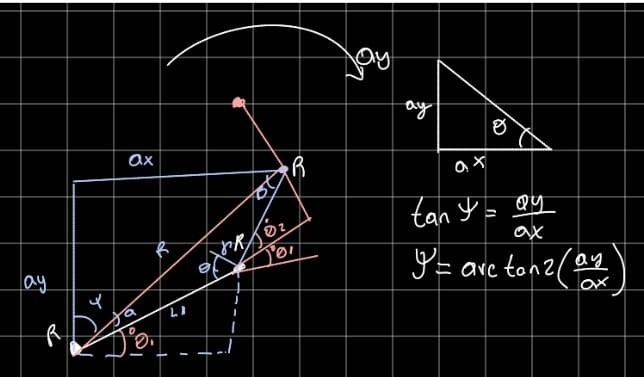

Phi=atan2(a_y,a_x)

$$Phi = \text{atan2}\left(L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right),L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{2}\,\cos\left(\theta_{O,1}\right)\right)$$

Se emplea la función **atan2**, ya que permite obtener soluciones en los cuatro cuadrantes del plano cartesiano. Por ello, resulta útil para garantizar que cualquier posición tenga una solución válida.

A partir de la imagen de referencia, se observa que el ángulo **ψ** corresponde a la suma de los ángulos **θ₀₁** y **α**. En consecuencia, se establece la siguiente relación:

De esta expresión se puede despejar 𝜃_0_1 como:

Para obtener la expresión de 𝜃_2_3, se sigue un procedimiento similar

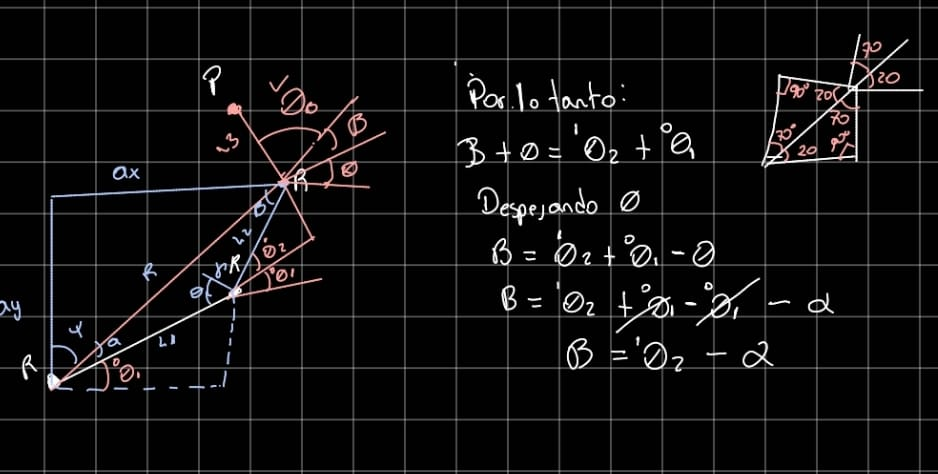

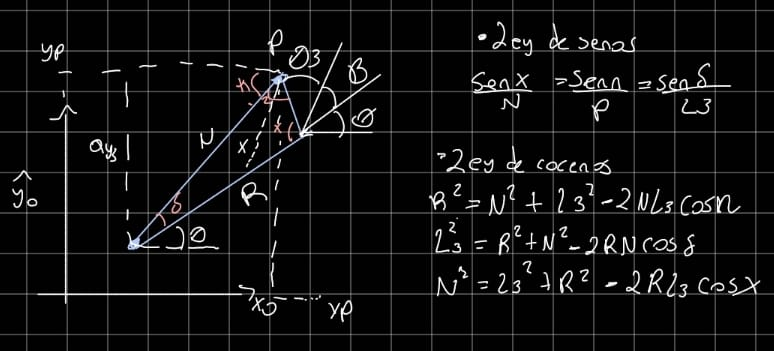

Se utiliza el teorema de Pitágoras para determinar la longitud del segmento 𝑁

Posteriormente, se despeja el ángulo χ de la ley de los cosenos. Dado que los ángulos χ, β y θ2,3 forman un ángulo π, se tiene la siguiente relación:

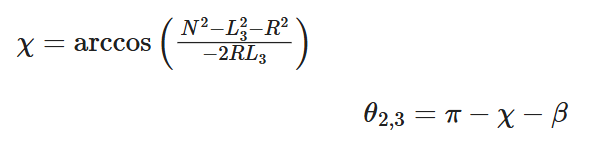

Para determinar el valor del ángulo 𝜅, se emplea la definición de la tangente:

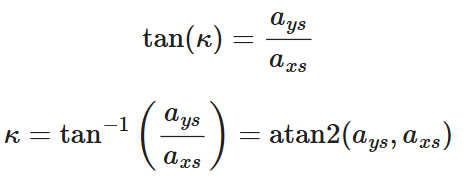

Finalmente, considerando la relación entre los ángulos, se tiene:

Con esto se obtiene la definición completa de cada uno de los ángulos que determinan las articulaciones del robot, lo que permite alcanzar la configuración deseada del punto **P** dentro del plano de trabajo.

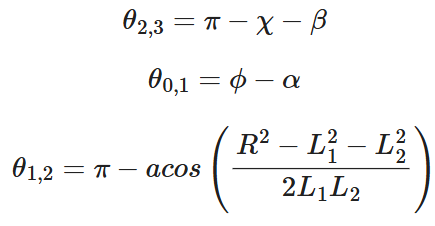

### Modelo cinemático directo de las velocidades

Para analizar las velocidades del robot, se utiliza la matriz Jacobiana (J). Esta matriz es una herramienta matemática fundamental que relaciona las velocidades de las articulaciones (el vector de velocidades angulares de los motores) con las velocidades del efector final (la velocidad lineal y angular de la "mano" del robot).

La relación se describe con la ecuación:


$$\dot{x} =J(q)\dot{q}$$


Donde:

- $\dot{x}$es el vector de velocidades del efector final.

-  $J(q)$es la matriz Jacobiana, que depende de la configuración actual del robot (los ángulos q).

- $\dot{q}$ es el vector de velocidades de las articulaciones.

A continuación se presenta el cálculo de la Jacobiana para este robot, así como de su inversa, la cual permite realizar el cálculo cinemático inverso de las velocidades.

syms J_theta

J_theta 

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_O_P,[theta_O_1, theta_1_2,theta_2_3])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

### Modelo cinemático inverso de las velocidades

Para obtener las velocidades articulares, se despeja el vector θ˙de la expresión de la cinemática directa de velocidades. Multiplicamos por ambos lados de la igualdad la inversa del jacobiano lo cual permite aislar las velocidades articulares:

Donde:

• θ˙ es el vector de velocidades articulares.

• x˙ es el vector de velocidad lineal y angular de la pose.

• J−1(θ) es la inversa del Jacobiano.

Normalmente, cuando el **Jacobiano** no es una matriz cuadrada —es decir, cuando el número de grados de libertad del robot no coincide con la dimensión del espacio de tareas se recurre al uso de la **seudo-inversa** para resolver la **cinemática inversa de velocidades**.

Sin embargo, en este caso particular, dado que el Jacobiano es una matriz cuadrada (**3×3**), es suficiente con calcular su **inversa directa** para obtener una solución exacta, siempre que el sistema no se encuentre en una **configuración singular**.

Una **configuración singular** se presenta en determinadas posiciones del robot en las que el efector final pierde uno o más grados de libertad, limitando así su capacidad de movimiento o control en ciertas direcciones del espacio de trabajo.

inv(J_theta)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$

## Rango de movimiento.

Otro aspecto importante a considerar es el **determinante del Jacobiano**, ya que este valor proporciona información relevante sobre el **espacio de trabajo** del robot **SCARA**. El determinante refleja la capacidad de movimiento del **efector final**: cuando su valor se aproxima a **cero**, el manipulador pierde uno o más **grados de libertad**, impidiendo su desplazamiento libre en determinadas direcciones dentro del espacio de trabajo.

d= det(J_theta)

$$d = L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)$$

determinante_J = simplify(d)

$$determinante\_J = L_{1}\,L_{2}\,\sin\left(\theta_{1,2}\right)$$

Para analizar este comportamiento, se estudian las **variables que influyen directamente en el determinante del Jacobiano**. Para la elaboración de la gráfica, se fijan las **longitudes de los eslabones** y se varía el **ángulo del que depende el determinante**, con el objetivo de observar cómo esta variación afecta la **capacidad de movimiento** del manipulador.

A continuación, se presenta el **código empleado** para realizar dicho análisis:

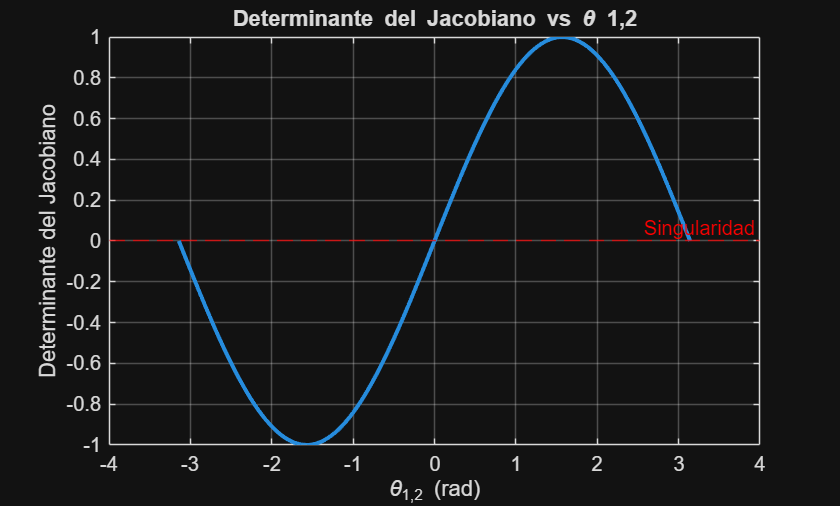

syms theta_1_2 L1 L2
detJ= L1 * L2 * sin(theta_1_2);
f_detJ= matlabFunction(detJ, 'Vars', [theta_1_2, L1, L2]);

%Rango de valores
theta_1_2_vals = linspace(-pi, pi , 500);
L1_val = 1;
L2_val =1;

%Evaluar determinante
det_vals = f_detJ(theta_1_2_vals, L1_val, L2_val);

%Grafica
figure  
plot(theta_1_2_vals, det_vals,'LineWidth',2)
xlabel('\theta_{1,2} (rad)')
ylabel('Determinante del Jacobiano')
title('Determinante del Jacobiano vs \theta {1,2}')
grid on
yline(0, '--r', 'Singularidad')

Se observa que, cuando el ángulo **θ₁₂** es igual a **cero**, el **determinante del Jacobiano** también toma el valor de **cero**. A medida que el ángulo incrementa hasta **π/2** (≈ 1.5708 rad), el determinante alcanza su **valor máximo**.

El valor del determinante está directamente influenciado por las **longitudes de los eslabones**: cuanto mayores sean dichas longitudes, **más amplio será el rango de movimiento** del sistema. En el análisis realizado, se consideraron **longitudes unitarias** con el fin de **simplificar el modelo** y facilitar la interpretación de los resultados.

### Modelo cinemático de las aceleraciones

El modelo cinemático de las aceleraciones se obtiene al derivar con respecto al tiempo el modelo de velocidades. Este análisis es crucial para el control dinámico del robot, ya que las aceleraciones están directamente relacionadas con las fuerzas y torques que los motores deben generar.

La ecuación que relaciona la aceleración del efector final ($\ddot{x}$) con las aceleraciones de las articulaciones ($\ddot{q}$) es:


$$\ddot{x} =\dot{J} (q,\dot{q} )\dot{q} +J(q)\ddot{q}$$


Donde $\dot{J}$ representa la derivada de la matriz Jacobiana con respecto al tiempo. A continuación, se procederá a calcular esta derivada y a construir el modelo completo.

% --- CÓDIGO DEFINITIVO PARA J_dot (Regla de la Cadena) ---

% 1. Definimos las velocidades de las articulaciones como nuevas variables simbólicas
syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

% 2. Creamos un vector de variables de articulación (q) y un vector de velocidades (q_dot)
% OJO: q_dot DEBE ser un vector columna (con punto y coma) para que funcione la multiplicación
q = [theta_O_1, theta_1_2, theta_2_3];
q_dot = [theta_dot_O_1; theta_dot_1_2; theta_dot_2_3];

% 3. Calculamos la derivada del Jacobiano (J_dot) usando la regla de la cadena
J_dot = sym(zeros(size(J_theta)));
for i = 1:length(q)
    J_dot = J_dot + diff(J_theta, q(i)) * q_dot(i);
end

% Mostramos el resultado final de J_dot
J_dot

$$J\_dot = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{1}-{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{3}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{3} & -\sigma_{1}-{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{3}\,\sigma_{3}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{3} & -L_{3}\,{\dot{\theta }}_{1,2}\,\sigma_{3}-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{3}-L_{3}\,{\dot{\theta }}_{O,1}\,\sigma_{3}\\ -{\dot{\theta }}_{O,1}\,\left(\sigma_{6}+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{5}\right)-\sigma_{2}-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{5} & -\sigma_{2}-{\dot{\theta }}_{O,1}\,\left(\sigma_{6}+L_{3}\,\sigma_{5}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{5} & -L_{3}\,{\dot{\theta }}_{1,2}\,\sigma_{5}-L_{3}\,{\dot{\theta }}_{2,3}\,\sigma_{5}-L_{3}\,{\dot{\theta }}_{O,1}\,\sigma_{5}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{\theta }}_{1,2}\,\left(\sigma_{4}+L_{3}\,\sigma_{3}\right)\\ \sigma_{2}={\dot{\theta }}_{1,2}\,\left(\sigma_{6}+L_{3}\,\sigma_{5}\right)\\ \sigma_{3}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{5}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Una vez obtenida la derivada del Jacobiano, se procede a derivar también el vector de velocidades articulares para completar el modelo cinemático de las aceleraciones.

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3
q_ddot = [theta_ddot_O_1; theta_ddot_1_2; theta_ddot_2_3];
q_ddot

$$q\_ddot = \left(\begin{array}{c} {\ddot{\theta }}_{O,1}\\ {\ddot{\theta }}_{1,2}\\ {\ddot{\theta }}_{2,3} \end{array}\right)$$

De este modo, se construye la expresión total de la aceleración del efector final.

Donde:

 es igual a:

syms theta_acel_O_1 theta_acel_1_2 theta_acel_2_3 
syms theta_acel1_O_1 theta_acel1_1_2 theta_acel1_2_3
dq = [theta_acel_O_1; theta_acel_1_2; theta_acel_2_3];
ddq = [theta_acel1_O_1; theta_acel1_1_2; theta_acel1_2_3];

dJ = sym(zeros(size(J_theta)));
theta_vec = [theta_O_1; theta_1_2; theta_2_3];
for i = 1:length(theta_vec)
    dJ = dJ + diff(J_theta, theta_vec(i)) * dq(i);
end
% Modelo cinemático directo de aceleraciones
ddx = simplify(dJ * dq + J_theta * ddq);
disp(ddx)

Adicionalmente, el control de la aceleración es indispensable para la planificación de trayectorias suaves y precisas. Al gestionar cómo cambia la velocidad, se evitan movimientos bruscos o "tirones" (jerk), lo cual es crítico para la integridad mecánica del manipulador y para la correcta ejecución de tareas delicadas como soldadura o ensamblaje.

## **Modelo Cinemático Inverso de Aceleraciones**

El modelo inverso se obtiene al despejar la aceleración de las articulaciones ($\ddot{q}$) de la ecuación del modelo directo. Este cálculo es esencial para los algoritmos de control que siguen trayectorias precisas.

La ecuación resultante es:


$$\ddot{q} =J^{-1} (q)(\ddot{x} -\dot{J} (q,\dot{q} )\dot{q} )$$


syms ddx1 ddx2 ddx3 real
ddx_vec = [ddx1; ddx2; ddx3];

ddq_inv= simplify(pinv(J_theta) * (ddx_vec - dJ * dq));
disp(ddq_inv)

Todos los componentes de esta ecuación ya han sido calculados simbólicamente en el script: la inversa del Jacobiano ($J^{-1}$) se obtuvo en la sección de velocidades, y la derivada del Jacobiano ($\dot{J}$) se acaba de calcular.

% --- Código Ilustrativo para el Modelo Cinemático Inverso de Aceleraciones ---

% 1. Definimos la entrada del problema: la aceleración deseada del efector final.
% Como es una ilustración, lo creamos como un vector simbólico genérico.
syms x_ddot_deseado y_ddot_deseado theta_ddot_deseado
x_ddot_in = [x_ddot_deseado; y_ddot_deseado; theta_ddot_deseado];

% 2. Calculamos la inversa del Jacobiano (J_inv).
J_inv = inv(J_theta);

% 3. Implementamos la fórmula de la cinemática inversa de aceleraciones:
% q_ddot = J_inv * (x_ddot_in - J_dot * q_dot)
q_ddot_calculado = J_inv * (x_ddot_in - J_dot * q_dot);

% 4. Mostramos el resultado simbólico (será una expresión muy grande).
% Le pedimos a MATLAB que lo simplifique para que sea más legible.
q_ddot_calculado = simplify(q_ddot_calculado)

### Modelo dinámico por ecuaciones de Eüler-Lagrange

El modelo dinámico describe la relación entre las fuerzas/torques aplicados por los motores y el movimiento resultante del robot, considerando factores como masas e inercias. En este reporte, se utiliza la formulación de Euler-Lagrange, un método basado en la energía del sistema.

Se calculan la energía cinética (K, por el movimiento) y la energía potencial (U, por la gravedad) de cada eslabón. El Lagrangiano (L = K - U) se utiliza para derivar las ecuaciones de movimiento que definen el torque ($\tau$) requerido en cada articulación para producir un movimiento deseado.

Se emplearan las siguientes ecuaciones para el cálculo de la energía cinética:


$$\$$



$$k_{i} = \frac{m_{i}}{2} \mathbf{v}_{C_{i}}^T \mathbf{v}_{C_{i}} + \frac{1}{2} \mathbf{\omega}_{C_{i}}^T \mathbf{I}_{C_{i}} \mathbf{\omega}_{C_{i}}


$$


syms x_1_C1 theta_dot_O_1

v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

$$v\_C1\_C1 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$

v_O_C1 = [-x_1_C1*sin(theta_O_1)*theta_dot_O_1;x_1_C1*cos(theta_O_1)*theta_dot_O_1;0]

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

transpose(v_C1_C1)*v_C1_C1

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

simplify(transpose(v_O_C1)*v_O_C1)

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

Para calcular el primer término de la energía cinética, correspondiente a la **velocidad lineal** de los centros de masa de cada eslabón, existen dos métodos válidos.

El primero consiste en realizar una **propagación de velocidades** desde el eslabón base hasta cada eslabón sucesivo. El segundo método consiste en calcular la **posición del centro de gravedad** de cada eslabón respecto al **sistema inercial de coordenadas**, y posteriormente derivar dicha posición para obtener la velocidad lineal.

**Propagación de velocidades**

Para aplicar el primer método mediante propagación de velocidades, se emplean las siguientes fórmulas:

velocidades angulares:

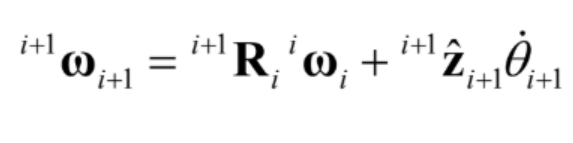

velocidades lineales:

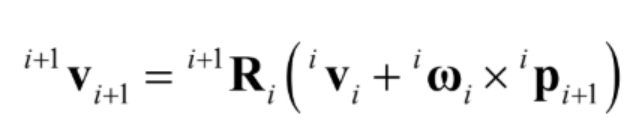

Se sacan la matriz de orientación de cada uno de los sistemas colocados en las juntas y se transpone. Estos datos se obtienen de la matriz de trasformaciones de cada junta con respecto al punto inmediato anterior (T_O_1, T_1_2, T_2_3).

Para R_O_1

R_0_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]

$$R\_0\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_0 = transpose(R_0_1)

$$R\_1\_0 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Para R_1_2

R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Para R_2_3

R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Para obtener las **velocidades lineales** de los centros de masa, es necesario calcular previamente las **velocidades angulares** de cada eslabón. Esto se logra definiendo un **vector unitario** que indique la dirección del eje de rotación. En este caso, dado que el movimiento ocurre alrededor del **eje Z**, se tiene:

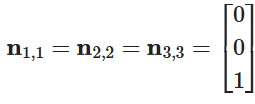

Se utiliza la transpuesta de la matriz de orientación que anteriormente se calculó, la derivada angular correspondiente a cada eslabón y la velocidad angular anterior.

syms omega_1_1 omega_2_2 omega_3_3
%Propagación para el primer cuerpo
omega_1_1

$$omega\_1\_1 = \omega_{1,1}$$

Para omega_0_0

omega_O_O=[0;0;0]

omega_O_O =      0
     0
     0


n_1_1 = [0;0;1]

n_1_1 =      0
     0
     1


R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

omega_1_1:

%Ecuación de propagación
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

omega_2_2:

%Propagación para el segundo cuerpo
omega_2_2

$$omega\_2\_2 = \omega_{2,2}$$

n_2_2 = [0;0;1]

n_2_2 =      0
     0
     1


R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$

omega_3_3:

%Propagación para el tercer cuerpo
omega_3_3

$$omega\_3\_3 = \omega_{3,3}$$

n_3_3 = [0;0;1]

n_3_3 =      0
     0
     1


R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%Ecuación de propagación
omega_3_3=R_3_2*omega_2_2+n_3_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

v_O_C3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Para la primera parte, la velocidad lineal del sistema uno utilizando la formula está dada por:

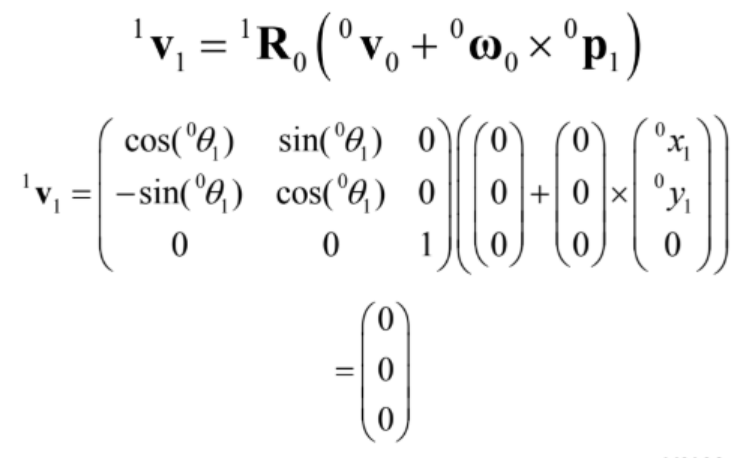

% --- Cálculo de la Velocidad Lineal v_1_1 ---

% La velocidad lineal de la base del robot (v_O_O) es cero.
v_O_O = [0;0;0];

% La velocidad angular de la base (omega_O_O) es cero.
% (Asegúrate de que esta línea esté con punto y coma en tu código).
omega_O_O = [0;0;0];

% El vector de posición desde el origen {O} al origen {1} es cero,
% ya que están en el mismo lugar.
p_O_1 = [0;0;0];

% Aplicamos la ecuación de propagación de la velocidad lineal:
% v_1_1 = R_1_O * (v_O_O + cross(omega_O_O, p_O_1))
v_1_1 = R_1_O * (v_O_O + cross(omega_O_O, p_O_1))

$$v\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Para el sistema 2 se tiene:

v_2_2 = R_2_1*(v_1_1 + cross(omega_1_1,[L1;0;0]))

$$v\_2\_2 = \left(\begin{array}{c} L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\\ L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\\ 0 \end{array}\right)$$

Para el sistema 3:

V_3_3 = simplify(R_3_2*(v_2_2+cross(omega_2_2,[L2;0;0])))    

$$V\_3\_3 = \left(\begin{array}{c} L_{2}\,{\dot{\theta }}_{1,2}\,\sin\left(\theta_{2,3}\right)+L_{2}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{2,3}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,{\dot{\theta }}_{1,2}\,\cos\left(\theta_{2,3}\right)+L_{2}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\\ 0 \end{array}\right)$$

Para calcular la **propagación de velocidades** hacia los centros de masa, se emplea la misma formulación utilizada en la propagación entre juntas, considerando adicionalmente que las **velocidades angulares** en el centro de masa de cada eslabón son iguales a las del sistema de coordenadas asociado a la junta correspondiente.

A continuación, se analiza el cálculo para el **centro de masa del primer eslabón**:

v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

$$v\_C1\_C1 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$

Para el centro de masa del segundo:

v_C2_C2 = ([1, 0, 0; 0, 1, 0; 0, 0, 1]*(v_2_2 + cross(omega_2_2,[x_2_C2; 0; 0])))

$$v\_C2\_C2 = \left(\begin{array}{c} L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\\ x_{2,\mathrm{C2}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\\ 0 \end{array}\right)$$

ssss

Para el centro de masa del tercer eslabón:

v_c3_c3 = ([1,0,0;0,1,0;0,0,1]*(V_3_3+cross(omega_3_3,[x_3_C3;0;0])))

$$v\_c3\_c3 = \left(\begin{array}{c} L_{2}\,{\dot{\theta }}_{1,2}\,\sin\left(\theta_{2,3}\right)+L_{2}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{2,3}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ x_{3,\mathrm{C3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+L_{2}\,{\dot{\theta }}_{1,2}\,\cos\left(\theta_{2,3}\right)+L_{2}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\\ 0 \end{array}\right)$$

Para estas velocidades, la matriz de orientación es la matriz identidad debido a que el sistema de la junta no cambia con respecto al del centro de masa.

## Cálculo de la posición de los centros de masa

Para hacerlo con el cálculo de la posición del centro de gravedad, se obtiene primero las trasformadas de cada punto de interés, suponiendo que el centro de masa de cada eslabón se encuentra justo en su punto medio. Se considera que el sistema de referencia asociado al centro de gravedad está orientado de manera idéntica al sistema de coordenadas del eslabón correspondiente.

La transformada de C1

syms x_1_C1 x_2_C2 x_3_C3

T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C1 = T_O_1*T_1_C1

$$T\_O\_C1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

La transformada de C2

T_2_C2 = Tij(x_2_C2,0,0,0,0,0)

$$T\_2\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{2,\mathrm{C2}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C2 = T_O_1*T_1_2*T_2_C2

$$T\_O\_C2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)-\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) & 0 & x_{O,1}+x_{2,\mathrm{C2}}\,\sigma_{1}+L_{1}\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2} & \sigma_{1} & 0 & y_{O,1}+x_{2,\mathrm{C2}}\,\sigma_{2}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

La transformada de C3

T_3_C3 = Tij(x_3_C3,0,0,0,0,0)

$$T\_3\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{3,\mathrm{C3}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C3 = T_O_1*T_1_2*T_2_3*T_3_C3

$$T\_O\_C3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{2,3}\right)\,\sigma_{4}-\sin\left(\theta_{2,3}\right)\,\sigma_{3} & 0 & x_{O,1}+L_{2}\,\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{1}\\ \sigma_{2} & \sigma_{1} & 0 & y_{O,1}+L_{2}\,\sigma_{4}+L_{1}\,\sin\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,3}\right)\,\sigma_{3}-\sin\left(\theta_{2,3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(\theta_{2,3}\right)\,\sigma_{4}+\sin\left(\theta_{2,3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

Se sacan los datos de la posición de cada trasformación.

Para P_O_C1

%Vectores de posición
p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]

$$p\_O\_C1 = \left(\begin{array}{c} x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

Para P_O_C2

p_O_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

$$p\_O\_C2 = \left(\begin{array}{c} x_{O,1}+x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

Para P_O_C3

p_O_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

$$p\_O\_C3 = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

## Cálculo de las velocidades

Para V_O_C1

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

v_O_C1 = diff(p_O_C1,theta_O_1)*theta_dot_O_1+diff(p_O_C1,theta_1_2)*theta_dot_1_2+diff(p_O_C1,theta_2_3)*theta_dot_2_3

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

Para V_O_C2

v_O_C2 = diff(p_O_C2,theta_O_1)*theta_dot_O_1+diff(p_O_C2,theta_1_2)*theta_dot_1_2+diff(p_O_C2,theta_2_3)*theta_dot_2_3

$$v\_O\_C2 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ 0 \end{array}\right)$$

Para V_O_C3

v_O_C3 = diff(p_O_C3,theta_O_1)*theta_dot_O_1+diff(p_O_C3,theta_1_2)*theta_dot_1_2+diff(p_O_C3,theta_2_3)*theta_dot_2_3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Cálculo de la velocidades angulares

syms omega_1_1 omega_2_2 omega_3_3
%Propagación para el primer cuerpo
omega_1_1

$$omega\_1\_1 = \omega_{1,1}$$

omega_O_O = [0;0;0]

omega_O_O =      0
     0
     0


n_1_1 = [0;0;1]

n_1_1 =      0
     0
     1


R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$


%Propagación para el segundo cuerpo
omega_2_2

$$omega\_2\_2 = \omega_{2,2}$$

n_2_2 = [0;0;1]

n_2_2 =      0
     0
     1


R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$


%Propagación para el tercer cuerpo
omega_3_3

$$omega\_3\_3 = \omega_{3,3}$$

n_3_3 = [0;0;1]

n_3_3 =      0
     0
     1


R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Ecuación de propagación
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

v_O_C3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

## Defición de los elementos de inercia 

syms g I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3
%vector de gravedad

g_v = [0;-g;0]

$$g\_v = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$


I_C1 = [I_xx1,0,0;0,I_yy1,0;0,0,I_zz1]

$$I\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & I_{\mathrm{yy1}} & 0\\ 0 & 0 & I_{\mathrm{zz1}} \end{array}\right)$$

I_C2 = [I_xx2,0,0;0,I_yy2,0;0,0,I_zz2]

$$I\_C2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}} & 0 & 0\\ 0 & I_{\mathrm{yy2}} & 0\\ 0 & 0 & I_{\mathrm{zz2}} \end{array}\right)$$

I_C3 = [I_xx3,0,0;0,I_yy3,0;0,0,I_zz3]

$$I\_C3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}} & 0 & 0\\ 0 & I_{\mathrm{yy3}} & 0\\ 0 & 0 & I_{\mathrm{zz3}} \end{array}\right)$$

Cáculo del Lagrangeano

syms m_1 m_2 m_3
%energía cinética de cada uno de los cuerpos

k_1 = simplify((m_1/2)*transpose(v_O_C1)*v_O_C1+(1/2)*transpose(omega_1_1)*I_C1*omega_1_1)

$$k\_1 = \frac{{{\dot{\theta }}_{O,1}}^{2}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)}{2}$$


k_2 = simplify((m_2/2)*transpose(v_O_C2)*v_O_C2+(1/2)*transpose(omega_2_2)*I_C2*omega_2_2)

$$k\_2 = \frac{m_{2}\,{L_{1}}^{2}\,{{\dot{\theta }}_{O,1}}^{2}}{2}+m_{2}\,\cos\left(\theta_{1,2}\right)\,L_{1}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}+m_{2}\,\cos\left(\theta_{1,2}\right)\,L_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{2,\mathrm{C2}}+\frac{m_{2}\,{{\dot{\theta }}_{1,2}}^{2}\,{x_{2,\mathrm{C2}}}^{2}}{2}+\frac{I_{\mathrm{zz2}}\,{{\dot{\theta }}_{1,2}}^{2}}{2}+m_{2}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}+\frac{m_{2}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{2,\mathrm{C2}}}^{2}}{2}+\frac{I_{\mathrm{zz2}}\,{{\dot{\theta }}_{O,1}}^{2}}{2}$$


k_3 = simplify((m_3/2)*transpose(v_O_C3)*v_O_C3+(1/2)*transpose(omega_3_3)*I_C3*omega_3_3)

$$k\_3 = \begin{array}{l} \frac{m_{3}\,{\left({\dot{\theta }}_{O,1}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\right)}^{2}}{2}+I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

% Cáclulo de la energía potencial de cada cuerpo

u_1 = -m_1*transpose(p_O_C1)*g_v

$$u\_1 = g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)$$

u_2 = -m_2*transpose(p_O_C2)*g_v

$$u\_2 = g\,m_{2}\,\left(y_{O,1}+x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)$$

u_3 = -m_3*transpose(p_O_C3)*g_v

$$u\_3 = g\,m_{3}\,\left(y_{O,1}+x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)$$

Cálculo del Lagrangeano


La = (k_1+k_2+k_3)-(u_1+u_2+u_3)

## Cálculo de los pares

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_theta1 = diff(La,theta_dot_O_1)

$$D\_theta1 = \begin{array}{l} I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{O,1}+{\dot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)+\frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,\sigma_{1}\,\left({\dot{\theta }}_{O,1}\,\sigma_{1}+{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,\sigma_{2}\,\left({\dot{\theta }}_{O,1}\,\sigma_{2}+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{6}\right)+{L_{1}}^{2}\,m_{2}\,{\dot{\theta }}_{O,1}+L_{1}\,m_{2}\,{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)+2\,L_{1}\,m_{2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{6}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$


% Cálculo de relación

tao_1 = diff(D_theta1,theta_O_1)*theta_dot_O_1 + diff(D_theta1,theta_1_2)*theta_dot_1_2 + diff(D_theta1,theta_2_3)*theta_dot_2_3 + diff(D_theta1,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta1,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta1,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_O_1)


D_theta2 = diff(La,theta_dot_1_2)

$$D\_theta2 = \begin{array}{l} I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{O,1}+\frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)\,\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\right)+m_{3}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\left({\dot{\theta }}_{O,1}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)+L_{1}\,m_{2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

tao_2 = diff(D_theta2,theta_O_1)*theta_dot_O_1 + diff(D_theta2,theta_1_2)*theta_dot_1_2 + diff(D_theta2,theta_2_3)*theta_dot_2_3 + diff(D_theta2,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta2,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta2,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_1_2)


D_theta3 = diff(La,theta_dot_2_3)

$$D\_theta3 = \begin{array}{l} \frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left({\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

tao_3 = diff(D_theta3,theta_O_1)*theta_dot_O_1 + diff(D_theta3,theta_1_2)*theta_dot_1_2 + diff(D_theta3,theta_2_3)*theta_dot_2_3 + diff(D_theta3,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta3,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta3,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_2_3)


tao = [tao_1;tao_2;tao_3]

% Cálculo de la matriz de inercia

M1 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[1,0,0,0,0,0,0])

$$M1 = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{zz1}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,{\sigma_{1}}^{2}+{L_{1}}^{2}\,m_{2}+m_{3}\,{\sigma_{2}}^{2}+m_{1}\,{x_{1,\mathrm{C1}}}^{2}+m_{2}\,{x_{2,\mathrm{C2}}}^{2}+2\,L_{1}\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ m_{2}\,{x_{2,\mathrm{C2}}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,\left(\sigma_{3}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\sigma_{1}+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}\right)\,\sigma_{2}\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\,\sigma_{1}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{6}\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{6}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

M2 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,1,0,0,0,0,0])

$$M2 = \begin{array}{l} \left(\begin{array}{c} m_{2}\,{x_{2,\mathrm{C2}}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)\\ I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{2}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,{\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)}^{2}+m_{3}\,{\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)}^{2}\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

M3 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,1,0,0,0,0])

$$M3 = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left(\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}\right)\\ m_{3}\,{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{2}}^{2}+m_{3}\,{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{1}}^{2}+I_{\mathrm{zz3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$


M_theta = collect([M1 M2 M3],[m_1,m_2,m_3])

$$M\_theta = \begin{array}{l} \left(\begin{array}{ccc} {x_{1,\mathrm{C1}}}^{2}\,m_{1}+\left({L_{1}}^{2}+2\,\cos\left(\theta_{1,2}\right)\,L_{1}\,x_{2,\mathrm{C2}}+{x_{2,\mathrm{C2}}}^{2}\right)\,m_{2}+\left({\sigma_{4}}^{2}+{\sigma_{5}}^{2}\right)\,m_{3}+I_{\mathrm{zz1}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & {x_{2,\mathrm{C2}}}^{2}\,m_{2}+\left({\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)}^{2}+{\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)}^{2}\right)\,m_{3}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}} & \sigma_{3}\\ \sigma_{2} & \sigma_{3} & \left({x_{3,\mathrm{C3}}}^{2}\,{\sigma_{6}}^{2}+{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{8}}^{2}\right)\,m_{3}+I_{\mathrm{zz3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left({x_{2,\mathrm{C2}}}^{2}+L_{1}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}\right)\,m_{2}+\left(\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)\,\sigma_{4}+\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)\,\sigma_{5}\right)\,m_{3}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}\\ \sigma_{2}=\left(x_{3,\mathrm{C3}}\,\sigma_{6}\,\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{8}\,\sigma_{5}\right)\,m_{3}+I_{\mathrm{zz3}}\\ \sigma_{3}=\left(x_{3,\mathrm{C3}}\,\sigma_{6}\,\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)+x_{3,\mathrm{C3}}\,\sigma_{8}\,\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)\right)\,m_{3}+I_{\mathrm{zz3}}\\ \sigma_{4}=\sigma_{7}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{6}\\ \sigma_{5}=x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{6}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{7}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{8}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{9}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Cálculo del vector de pares de

V_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,0])

G_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,0,0,0,g])

$$G\_theta = \begin{array}{l} \left(\begin{array}{c} g\,m_{3}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{1}\right)+g\,m_{2}\,\left(x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ g\,m_{3}\,\left(\sigma_{2}+\sigma_{1}\right)+g\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ g\,m_{3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

#### Cálculo del modelo  Dinámico directo

Para el cálculo del modelo dinámico se obtiene tau de manera simbólica con la matriz de inercia (M_theta) y el vector de pares (V_theta y G_theta).

tau = M_theta * [theta_ddot_O_1; theta_ddot_1_2; theta_ddot_2_3] + V_theta + G_theta;
disp(tau)

## Calculo del modelo dinamico inverso

Invtheta_ddot = inv(M_theta) * (tau - V_theta - G_theta);
disp(Invtheta_ddot)

## Concluciones

Al finalizar este reporte, se ha cumplido con el objetivo principal de desarrollar y documentar de manera integral el modelo matemático de un robot SCARA de tres grados de libertad. Este proceso no solo consistió en la aplicación de fórmulas, sino en la construcción de un verdadero "gemelo digital" que nos permite comprender y predecir el comportamiento del robot. A través de este desarrollo, se ha podido constatar que la cinemática y la dinámica son dos caras de la misma moneda. Mientras que la cinemática nos proporciona el "mapa" del movimiento del robot, permitiéndonos saber dónde está y cómo llegar a un punto, la dinámica nos da la "fuerza" para seguir ese mapa, conectando el movimiento abstracto con la realidad física de los motores, las inercias y la gravedad. Un aprendizaje clave fue entender cómo el Jacobiano y su derivada son el puente fundamental entre la postura y el movimiento a alta velocidad. El desarrollo del modelo dinámico mediante la formulación de Euler-Lagrange resultó ser la etapa más compleja, generando ecuaciones de gran extensión. Esto resalta la importancia y la potencia de las herramientas de cálculo simbólico como MATLAB, sin las cuales el manejo de dicha complejidad sería una tarea prácticamente irrealizable a mano.

Con este modelo completo, el siguiente paso lógico y fundamental es la simulación. La validación de estos modelos en un entorno virtual permitirá probar trayectorias y estrategias de control de forma segura y eficiente, antes de su implementación en un manipulador físico, cerrando así el ciclo de diseño y análisis en la robótica.